# Standard Propagation Model (SPM)

## Calculates distance based on Standard Propagation Model of Atoll.

- Diffraction Losses assumed to be Zero.

- Clutter Losses are Optional.

### Inputs:

- Path Loss (dB).

- Frequency (MHz).

- Transmitter Height (m).

- Receiver Height (m).

- `(optional) `Clutter Map [Path of clutter classes file].

- `(optional)` Clutter Losses [Path to txt file with losses].

### Output:

- Distance (m).

function d = SPM(PL,f,h_TX,h_RX,ClutterMap,ClutterLosses)
    k2=44.9;
    k3=5.83;
    k4=1;
    Diffraction=0;
    k5=-6.55;
    k6=0;
    k7=0;
    k_clutter=1;
    f_clutter=0;

    if exist("ClutterMap","var") && exist("ClutterLosses","var")


        Clutter=readgeoraster(ClutterMap);

        ClutterHist=imhist(Clutter);
        
        o=1;
        for i=ClutterLosses
            o=o+1;
            f_clutter=f_clutter+i*ClutterHist(o)/sum(ClutterHist);
        end


    end

    if f<=935
        k1=12.5;
    elseif f<=1805
        k1=17.4;
    elseif f<=1900
        k1=22;
    elseif f<=1930
        k1=23;
    elseif f<=2110
        k1=23;
    elseif f<=2300
        k1=23.8;
    elseif f<=2500
        k1=24.7;
    elseif f<=2700
        k1=25.4;
    elseif f<=3300
        k1=26.1;
    elseif f<=3500
        k1=27.8;
    else
        k1=28.3;
    end
    
    d=10^((PL-k1-k3*log10(h_TX)-k4*Diffraction-k6*h_RX-k7*log10(h_RX)-k_clutter*f_clutter)/(k2+k5*log10(h_TX)));

end

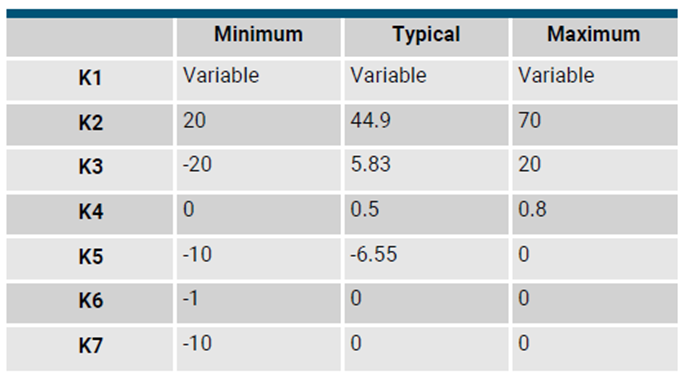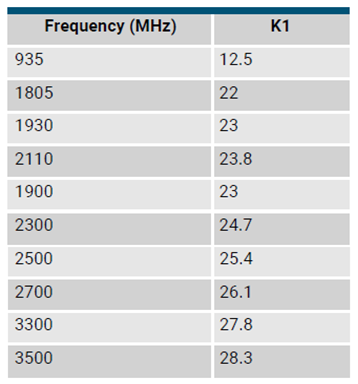

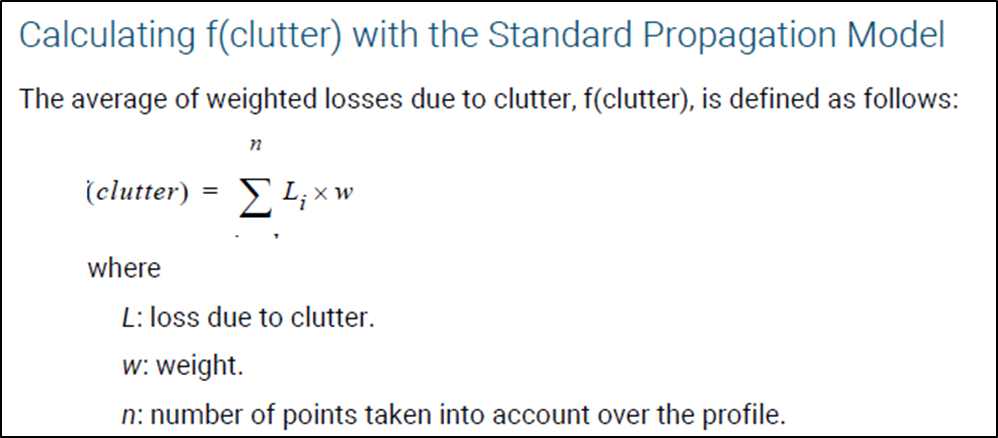

## **References:**

- **Atoll User Manual Radio.**

- **Atoll Technical Reference Guide Radio.**